## Testing the kinematic model

addpath("Kinematics")
clear all; close all;



Creating valid position as starting position

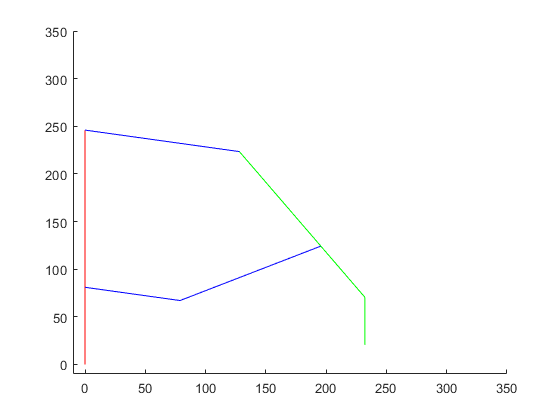

pos1 = ArmPos();
X = -10;
Z = -10;
pos1.phiX = X/360 * 2 * pi;
pos1.phiZ = Z/360 * 2 * pi;
pos1 = pos1.phiZXtoFullpos(false);

pos1.draw();

### Creating copy of position and moving end effector

dr = -10

dr = -10

dz = 10

dz = 10

pos2 = pos1;
pos2.C = pos2.C + [dr,dz];
pos2 = pos2.setD;
%pos2.draw();
pos2.validate(false); %should return as invalid position

### Computing new possible solutions

tic
r1 = KineMod.CtoA(pos2);
r2 = KineMod.BtoE(r1);
toc

Elapsed time is 0.005450 seconds.


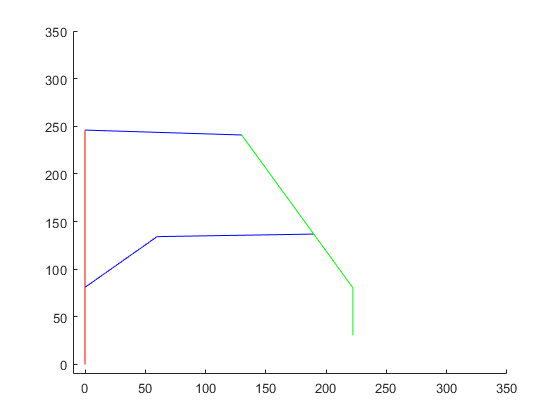

ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: 0.2000
    phiXmax: 1.4708
    phiZmin: -0.4000
    phiZmax: 0.3000
    phi1min: -0.7854
    phi1max: 0.7854
          A: [129.8987 240.8680]
          B: [189.7323 136.8491]
          C: [222.1423 80.5055]
          D: [222.1423 30.5055]
          E: [59.7596 134.1864]
       phiX: 0.7273
       phiZ: -0.0395
       phi1: -0.7068



for i=1:length(r2)
    r2(i).draw()
end

KineMod.kinDist(pos1,r2)

ans = 101.1627

KineMod

ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: 0.2000
    phiXmax: 1.4708
    phiZmin: -0.4000
    phiZmax: 0.3000
    phi1min: -0.7854
    phi1max: 0.7854
          A: [129.8987 240.8680]
          B: [189.7323 136.8491]
          C: [222.1423 80.5055]
          D: [222.1423 30.5055]
          E: [59.7596 134.1864]
       phiX: 0.7273
       phiZ: -0.0395
       phi1: -0.7068



KineMod.negativePhi1(r2)

x = ArmPos();
j = 0;
r_start =0;
r_end = 400;
z_start = 0;
z_end = 220;
tic
failuremap = zeros(z_start-z_end+1,r_end-r_start+1);
for r=r_start:r_end
    for z=z_start:z_end

        x.C = [r,z];
        [r1, error1] = KineMod.CtoA(x);
        if error1
            failuremap(z-z_start+1,r-r_start+1)  = 1;
            continue
        end
        [r2, error2] = KineMod.BtoE(r1);
        if error2
            failuremap(z-z_start+1,r-r_start+1)  = 1;
            continue
        end
        j = j + 1;
        failuremap(z-z_start+1,r-r_start+1) = 0;
        result(z-z_start+1,r-r_start+1) = KineMod.negativePhi1(r2);
    end
    
end
toc
j

failuremap

figure()
clf
imshow(flipud(failuremap))

result(69,31).draw();

x = ArmPos();
x.C = [200,50];
[r1, error1] = KineMod.CtoA(x);
[r2, error2] = KineMod.BtoE(r1)

tic
y = KineMod.IK_MAU([200,50],true)
toc
y.draw()

